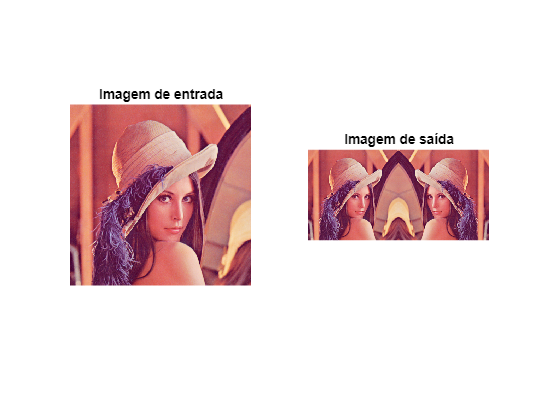

P = imread("Lenna.tif");

[num_linhas, num_colunas, num_canais] = size(P);

R = uint8(zeros(num_linhas, 2*num_colunas, num_canais));

R(:, 1:num_colunas, :) = P;

P_espelhada = fliplr(P);

R(:, num_colunas+1:end, :) = P_espelhada;

subplot(1,2,1), imshow(P), title('Imagem de entrada');
subplot(1,2,2), imshow(R), title('Imagem de saída');